clear

addpath("matlab_functions\")

load('data/Sensitivity_100Hz.mat')
lim = 20e-3;

mask = -lim < element_centers(1,:) &  element_centers(1,:) < lim & ...
       -lim < element_centers(2,:) &  element_centers(2,:) < lim & element_centers(3,:) > -1.5e-3;

S = S(:, mask);
element_centers = element_centers(:, mask);

[Lx,Ly,Lz] = grad_operator(element_centers);

B0 = readmatrix('data/B_defectless.txt');
B0 = B0(:, 2:end).';

B = readmatrix('data/B_defect4.txt');
B = B(:, 2:end).';

delta_B = B - B0;
delta_B = delta_B(:,3);

clear B0 B 

lambda = 1e-5;

beta = 1e-35;

R = decomposition(S' * S + beta * (Lx' * Lx) + beta * (Ly' * Ly));
delta_sigma = zeros(size(S,2), 1);
dx = zeros(size(S,2), 1);
bx = zeros(size(S,2), 1);
dy = zeros(size(S,2), 1);
by = zeros(size(S,2), 1);

tic
for i = 1:100
    delta_sigma = R \ (S' * delta_B + beta * Lx' * (dx - bx) + beta * Ly' * (dy - by));
    dx = sthresh(Lx * delta_sigma + bx, lambda/beta);
    dy = sthresh(Ly * delta_sigma + by, lambda/beta);
    bx = bx + (Lx * delta_sigma - dx);
    by = by + (Ly * delta_sigma - dy);
end
toc

Elapsed time is 0.172537 seconds.



clear lambda beta R dx dy bx by i

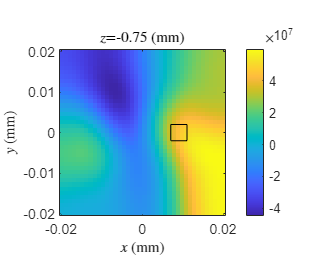

z = unique(element_centers(3,:));
z = sort(z, 'descend');

c = real(-delta_sigma);

figure('Position',[10 10 300 250*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    imagesc([-lim lim],[-lim lim], c_layer.', [min(c) max(c)])
    rectangle('Position', [7 -2 4 4] * 1e-3)
    colorbar
    axis square xy
    title(sprintf('$z$=%g (mm)',z(k)*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
end


clear lim mask k z c c_layer

function x = sthresh(x, gamma)
xs = abs(x) - gamma;
xs(xs < 0) = 0;
x = xs .* sign(x);
end

function [Lx,Ly,Lz] = grad_operator(element_centers)

n = size(element_centers,2);
nx = length(unique(element_centers(1,:)));
ny = length(unique(element_centers(2,:)));
nz = length(unique(element_centers(3,:)));

x   = reshape(element_centers(1,:), nx,ny,nz);
y   = reshape(element_centers(2,:), nx,ny,nz);
z   = reshape(element_centers(3,:), nx,ny,nz);
idx = reshape(1:n, nx,ny,nz);

assert(all(x == x(:,1,1), 'all')); x = x(:,1,1); assert(issorted(x));
assert(all(y == y(1,:,1), 'all')); y = y(1,:,1); assert(issorted(y));
assert(all(z == z(1,1,:), 'all')); z = z(1,1,:); assert(issorted(z));

Lx = sparse(n,n);
Ly = sparse(n,n);
Lz = sparse(n,n);

for i = 1:nx
for j = 1:ny
for k = 1:nz
    idx_0 = idx(i,j,k);

    if i < nx
        idx_x = idx(i+1,j,k);
        dx = x(i+1) - x(i);
        Lx(idx_0, idx_0) =  1/dx;
        Lx(idx_0, idx_x) = -1/dx;
    end
    if j < ny
        idx_y = idx(i,j+1,k);
        dy = y(j+1) - y(j);
        Ly(idx_0, idx_0) =  1/dy;
        Ly(idx_0, idx_y) = -1/dy;
    end
    if k < nz
        idx_z = idx(i,j,k+1);
        dz = z(k+1) - z(k);
        Lz(idx_0, idx_0) =  1/dz;
        Lz(idx_0, idx_z) = -1/dz;
    end
end
end
end

end